## MathTool HW6

## 2024-12-13

### Question 2 Reverse Correlation

clear all; clc; close all;
addpath("hw6-files/");

## Part a)

kernel = [1 2 1; 2 4 2; 1 2 1] / 6;
kernel_flat = kernel(:);

%Stimuli
duration = 100;
[spikes, stimuli] = runGaussNoiseExpt(kernel_flat, duration);
filter_response = stimuli * kernel_flat;

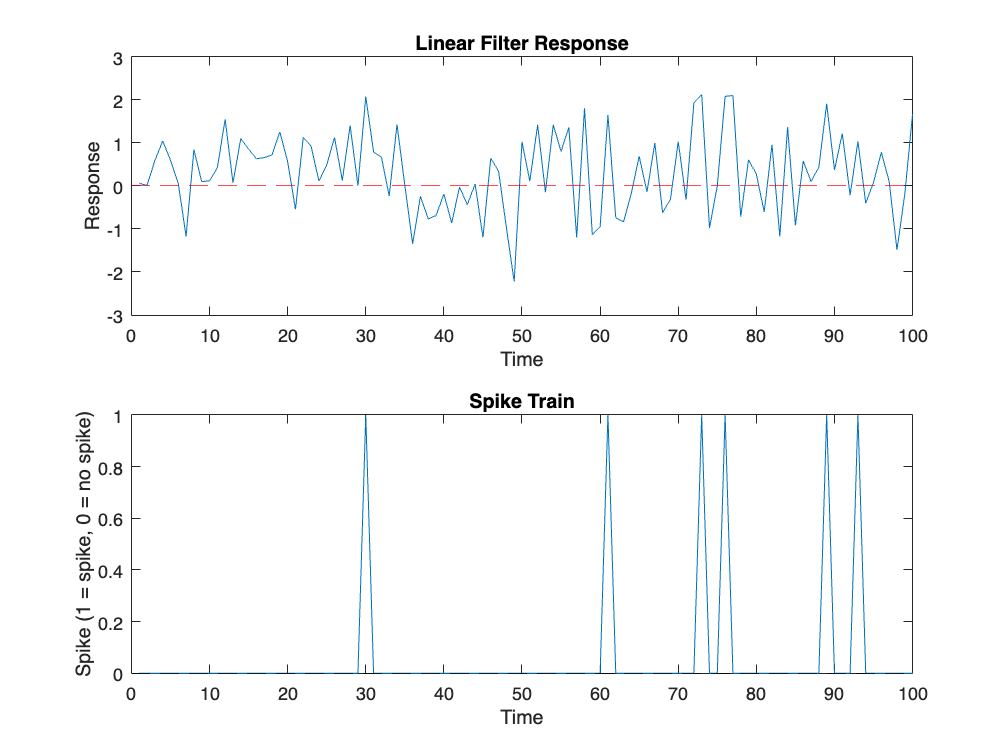

figure;
subplot(2,1,1);
plot(filter_response);
yline(0, 'r--');
title('Linear Filter Response');
xlabel('Time');
ylabel('Response');

subplot(2,1,2);
plot(spikes);
yline(0, 'k--');
title('Spike Train');
xlabel('Time');
ylabel('Spike (1 = spike, 0 = no spike)');

The spike tend to occur when the linear filter response is relatively peaking. Because spikes are more likely to be generated when the stimulus produces a large positive response after being filtered by the kernel, which we can interpret it as exceeding some threshold.

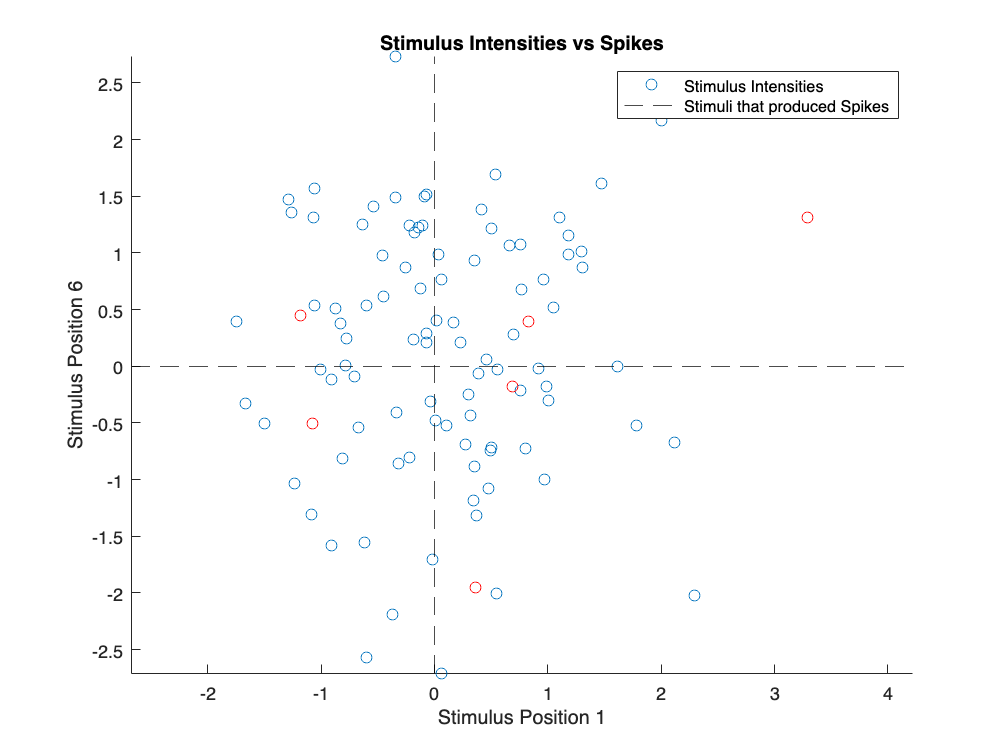

% 2D Scatter Plot
stimulus_1_6 = stimuli(:, [1, 6]); 
figure;
scatter(stimulus_1_6(:,1), stimulus_1_6(:,2), 'o');
xline(0, 'k--');
yline(0, 'k--');
hold on;
spike_positions = stimuli(spikes == 1, [1, 6]); 
scatter(spike_positions(:,1), spike_positions(:,2), 'ro');
axis equal;
title('Stimulus Intensities vs Spikes');
xlabel('Stimulus Position 1');
ylabel('Stimulus Position 6');
legend({'Stimulus Intensities', 'Stimuli that produced Spikes'});

It does look like a 2D Gaussian since the points are spread symmetrically around the origin. Also, the density points gradually decreases as moving farther away from the center.

The spikes tend to appear around moderate positive values for **Stimulus Position 1** and close-to-zero values for **Stimulus Position 6, **showing that it's aligning with the kernel.

This does match our expectation, since:

- The kernel acts as a spatial filter, and spikes occur when the stimulus matches or correlates well with the kernel.

- Most of the stimulus intensities are near the center, with fewer points farther from the origin, which is because of the stimuli are drawn from a Gaussian distribution.

- Spikes in Gaussian space is well-aligned with pattern in linear filter response space. 

## Part b)

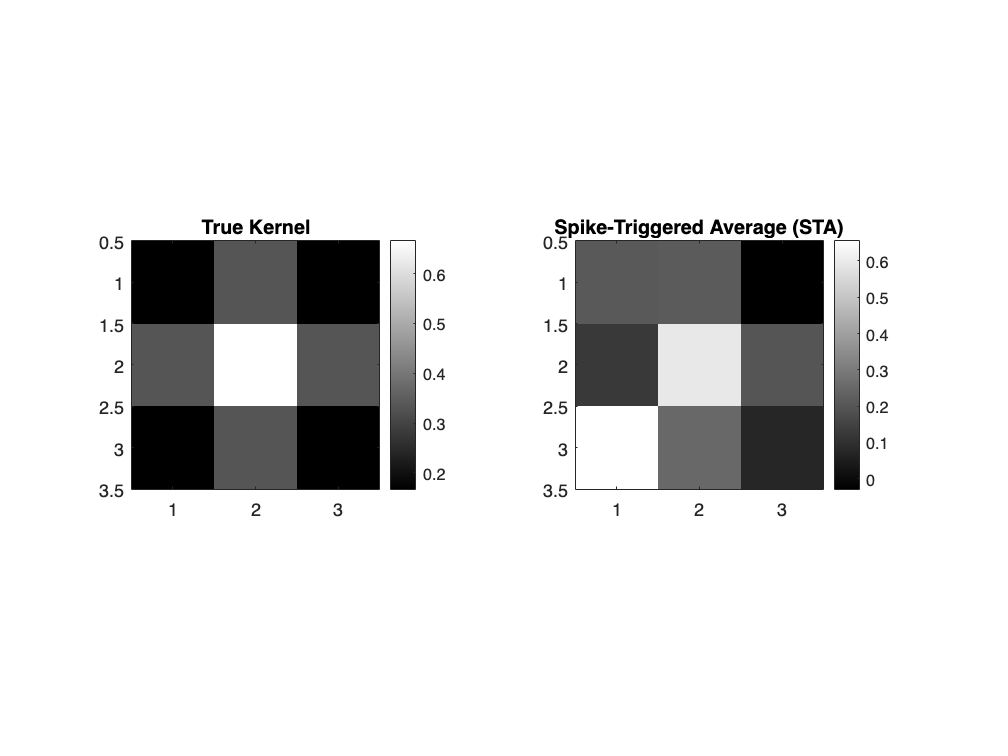

kernel = [1 2 1; 2 4 2; 1 2 1] / 6;
kernel_flat = kernel(:); 
duration = 100; 
[spikes, stimuli] = runGaussNoiseExpt(kernel_flat, duration);
if sum(spikes) > 0  
    STA = mean(stimuli(spikes == 1, :), 1);  
else
    STA = zeros(1, length(kernel_flat));
end
STA_mean=mean(STA);

STA = STA / norm(STA);
STA_matrix = reshape(STA, size(kernel));

figure;
subplot(1, 2, 1);
imagesc(kernel);
colormap gray;
colorbar;
axis equal tight;
title('True Kernel');

subplot(1, 2, 2);
imagesc(STA_matrix);
colormap gray;
colorbar;
axis equal tight;
title('Spike-Triggered Average (STA)');

similarity = corr(kernel_flat, STA');

disp(['Mean of STA: ', num2str(STA_mean)]);

Mean of STA: 0.62531


disp(['Similarity (correlation) between STA and true kernel: ', num2str(similarity)]);

Similarity (correlation) between STA and true kernel: 0.44563


It's around 73% similar between the true kernel and the STA, with center being most activated in both.

durations = [100, 400, 1600, 6400, 25600, 102400];
nRuns = 100;

biases = zeros(1, length(durations));
variances = zeros(1, length(durations));

for d = 1:length(durations) %durations
    duration_b = durations(d);
    STAs = zeros(length(kernel_flat), nRuns); %empty holder

    for r = 1:nRuns %runs
        [spikes, stimuli] = runGaussNoiseExpt(kernel_flat, duration_b);

        spike_indices = find(spikes == 1);
        if isempty(spike_indices)
            STA_b = zeros(size(kernel_flat));  
        else
            spike_b = length(spike_indices);
            STA_b = zeros(spike_b, length(kernel_flat));
            for i = 1:spike_b
                if spike_indices(i) < 6
                    STA_b(i, :) = mean(stimuli(1:spike_indices(i), :), 1);
                else
                    STA_b(i, :) = mean(stimuli(spike_indices(i)-5:spike_indices(i), :), 1);
                end
            end
            STA_b = mean(STA_b, 1); 
        end

        STA_b = STA_b(:) / norm(STA_b);
        STAs(:, r) = STA_b;
    end %runs

    %mean
    mean_STA = mean(STAs, 2);

    %bias
    bias_kernel = mean_STA - kernel_flat;
    biases(d) = norm(bias_kernel);

    %variance
    differences = STAs - mean_STA;
    variances(d) = mean(sum(differences.^2, 1));
end %durations


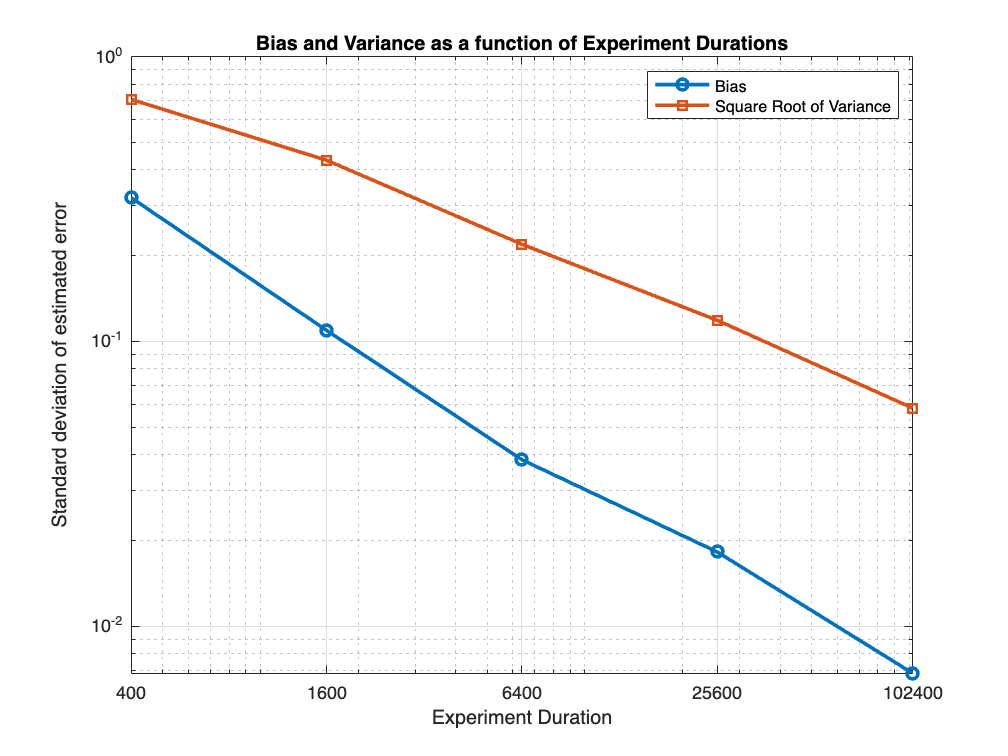

figure;
loglog(durations, biases, 'o-', 'LineWidth', 2);
hold on;
loglog(durations, sqrt(variances), 's-', 'LineWidth', 2);
legend('Bias', 'Square Root of Variance');
xlabel('Experiment Duration');
ylabel('Standard deviation of estimated error');
title('Bias and Variance as a function of Experiment Durations');
grid on;

xticks(durations);
xticklabels(arrayfun(@num2str, durations, 'UniformOutput', false));

From the graph we can see that **bias** decreases proportionally as the experiment duration increases. Longer durations allow for better averaging of the stimuli that caused spikes, leading to an STA that better approximates the true kernel. This indicates that STA estimate becomes more accurate as more data is gathered, which is overall decreasing estimated error.

The **square root of the variance** also decreases as the experiment duration increases. Increasing the number of trials reduces the effect of random variability in STA. This reflects the fact that random noise in the STA estimates reduces with more data.

Overall, we can caonclude that both systematic and random errors reduce with increasing sample size.

## Part c)

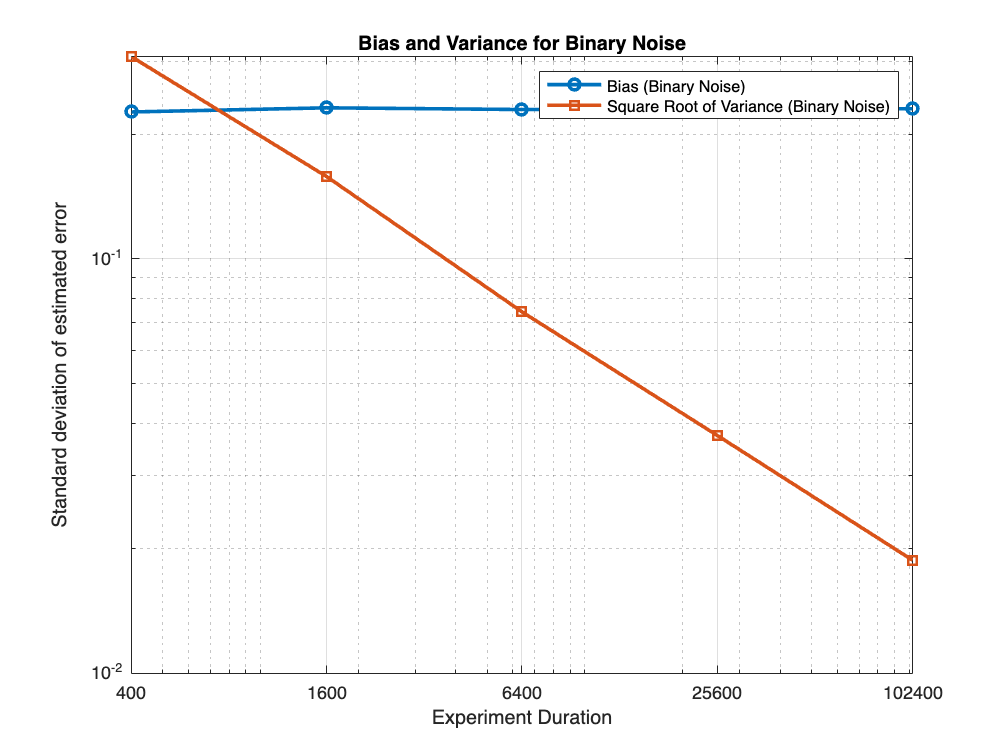

kernel_c = [1 2 1; 2 4 2; 1 2 1] / 6;
kernel_flat_c = kernel_c(:);

durations = [100, 400, 1600, 6400, 25600, 102400];
nRuns = 100;

biases_bin = zeros(1, length(durations));
variances_bin = zeros(1, length(durations));

for dIdx = 1:length(durations)
    duration_c = durations(dIdx);
    STAs_bin = zeros(length(kernel_flat_c), nRuns); 

    for r = 1:nRuns
        [spikes, stimuli] = runBinNoiseExpt(kernel_flat_c, duration_c);

        spike_indices = find(spikes == 1);
        if isempty(spike_indices)
            STA_c = zeros(size(kernel_flat_c));
        else
            STA_c = mean(stimuli(spike_indices, :), 1);
            STA_c = STA_c(:);
        end

        STA_c = STA_c / norm(STA_c);
        STAs_bin(:, r) = STA_c;
    end

    mean_STA_bin = mean(STAs_bin, 2);

    %bias
    bias_kernel_bin = mean_STA_bin - kernel_flat_c;  
    biases_bin(dIdx) = norm(bias_kernel_bin); 

    %variance
    diffs_bin = STAs_bin - mean_STA_bin;
    variances_bin(dIdx) = mean(sum(diffs_bin.^2, 1));
end

figure;
loglog(durations, biases_bin, 'o-', 'LineWidth', 2);
hold on;
loglog(durations, sqrt(variances_bin), 's-', 'LineWidth', 2);
legend('Bias (Binary Noise)', 'Square Root of Variance (Binary Noise)');
xlabel('Experiment Duration');
ylabel('Standard deviation of estimated error');
title('Bias and Variance for Binary Noise');
grid on;

xticks(durations);
xticklabels(arrayfun(@num2str, durations, 'UniformOutput', false));

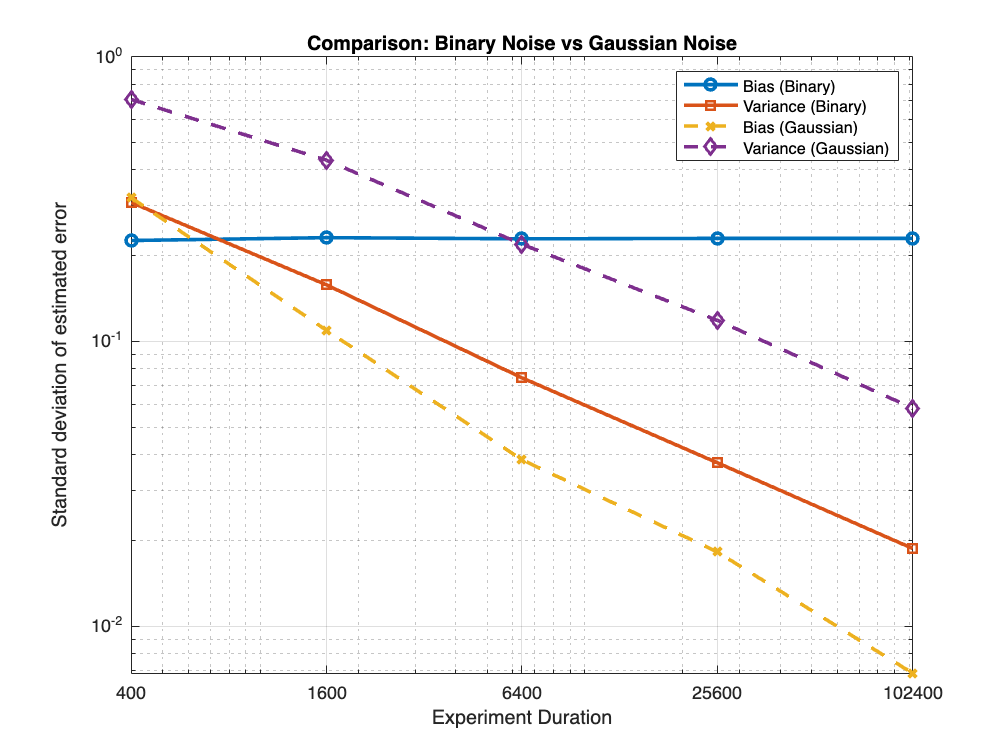

% Compare with Gaussian noise (overlaid plot)
figure;
loglog(durations, biases_bin, 'o-', 'LineWidth', 2);
hold on;
loglog(durations, sqrt(variances_bin), 's-', 'LineWidth', 2);
loglog(durations, biases, 'x--', 'LineWidth', 2);  %G
loglog(durations, sqrt(variances), 'd--', 'LineWidth', 2); %G
legend('Bias (Binary)', 'Variance (Binary)', 'Bias (Gaussian)', 'Variance (Gaussian)');
xlabel('Experiment Duration');
ylabel('Standard deviation of estimated error');
title('Comparison: Binary Noise vs Gaussian Noise');
grid on;
xticks(durations);
xticklabels(arrayfun(@num2str, durations, 'UniformOutput', false));

For binary noise, since it's discrete of binary stimuli restricts their ability to approximate the kernel's continuous profile, so it has a fixed systematic error (representing relatively constant bias). On the otherhand, Gaussian noise is continous, so it introduces more variability. 

For variance, the binary noise exhibits lower variance compared to Gaussian noise, especially for short experiment durations, because binary stimuli have limited variability. Gaussian noise has higher initial variance but reduces both bias and variance more effectively with increasing data.

Overall, we can see that binary noise shows a constant bias due to its discrete nature, while Gaussian noise reduces bias with more data. Binary noise has lower variance initially but both noise types reduce variance with more data.

Afterall, I would say that Gaussian noise is better for capturing the true kernel with enough data, while binary noise provides more stable but systematically **biased** estimates.

## Part d)

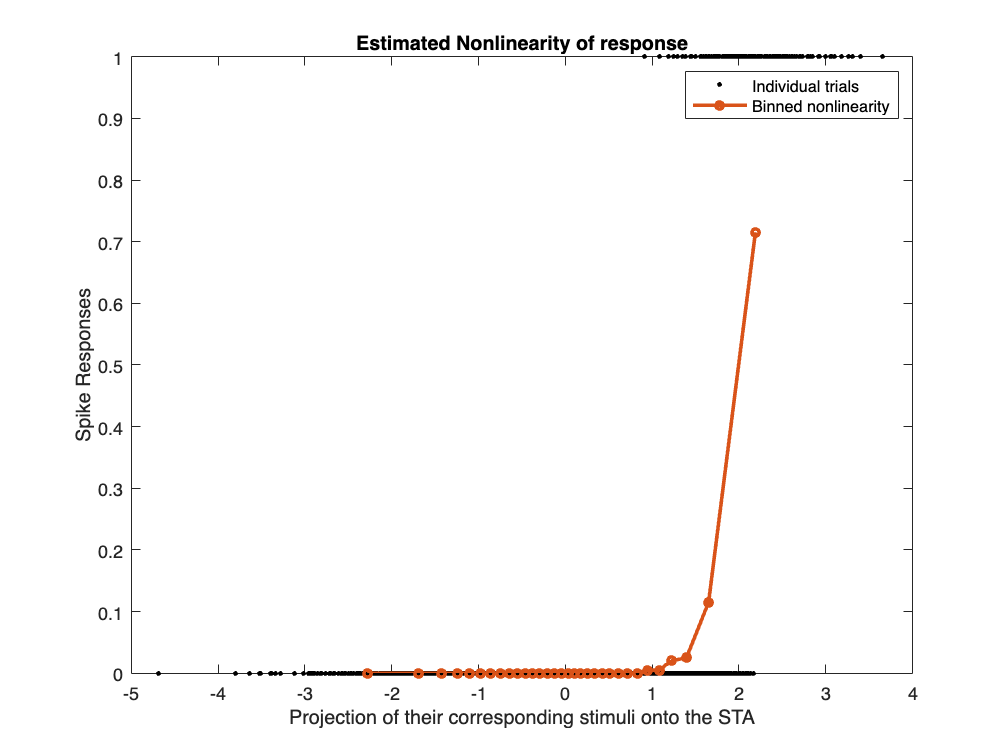

duration = 6400;
kernel_d = [1 2 1; 2 4 2; 1 2 1] / 6;
kernel_flat_d = kernel_d(:);

[spikes, stimuli] = runGaussNoiseExpt(kernel_flat_d, duration);

%Single run STA
spike_indices = find(spikes == 1);
if ~isempty(spike_indices)
    STA_d = mean(stimuli(spike_indices, :), 1);  
else
    STA_d = zeros(1, length(kernel_flat_d));
end
STA_d = STA_d(:) / norm(STA_d); 

%projection
projections = stimuli * STA_d;

[projectionsNew, sort_indices] = sort(projections, 'descend');
spikesNew = spikes(sort_indices);


sizeBin = 200;
nBins = duration / sizeBin;
meanProjection = zeros(nBins, 1);
meanSpike = zeros(nBins, 1);

%mean projection values and spike probabilities in each bin
for bin = 1:nBins
    bin_range = (bin-1)*sizeBin + 1 : bin*sizeBin;
    meanProjection(bin) = mean(projectionsNew(bin_range));
    meanSpike(bin) = mean(spikesNew(bin_range));
end


figure;
plot(projectionsNew, spikesNew, 'k.', 'MarkerSize', 8);
hold on;
plot(meanProjection, meanSpike, 'o-', 'LineWidth', 2, 'MarkerSize', 4);

xlabel('Projection of their corresponding stimuli onto the STA');
ylabel('Spike Responses');
title('Estimated Nonlinearity of response');
legend('Individual trials', 'Binned nonlinearity');

## Part e)

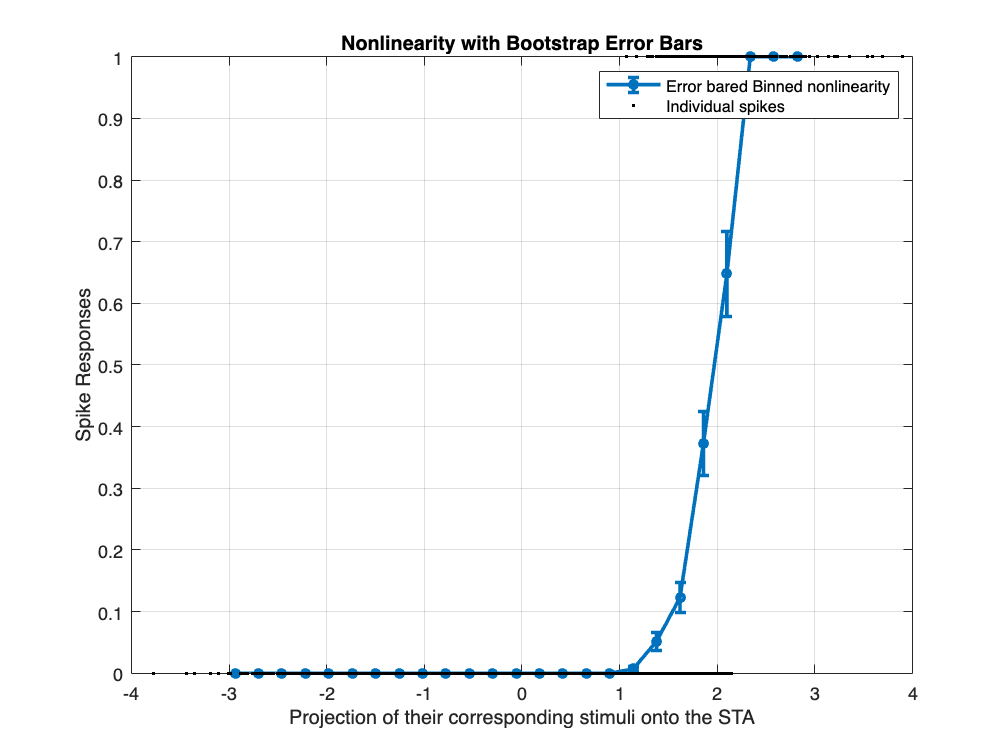

duration_e = 6400;
kernel_e = [1 2 1; 2 4 2; 1 2 1] / 6;
kernel_flat_e = kernel_e(:);

[spikes, stimuli] = runGaussNoiseExpt(kernel_flat_e, duration_e);

spike_indices = find(spikes == 1);
STA_e = zeros(1, length(kernel_flat_e));
if ~isempty(spike_indices)
    STA_e = mean(stimuli(spike_indices, :), 1); 
end
STA_e = STA_e(:) / norm(STA_e); 

projections_e = stimuli * STA_e;

nBins_e = 32;
binEdges = linspace(min(projections_e), max(projections_e), nBins_e + 1);
binCenters = (binEdges(1:end-1) + binEdges(2:end)) / 2;

mean_spike_in_bin = arrayfun(@(b) ...
    mean(spikes((projections_e >= binEdges(b)) & (projections_e < binEdges(b+1)))), ...
    1:nBins_e)';

nbootstrap = 100;
bootstrap_spike_bins = zeros(nbootstrap, nBins_e);

for i = 1:nbootstrap
    rand_indices = randi(duration_e, [duration_e, 1]);
    proj_resampled = projections_e(rand_indices);
    spikes_resampled = spikes(rand_indices);
    
    bootstrap_spike_bins(i, :) = arrayfun(@(b) ...
        mean(spikes_resampled((proj_resampled >= binEdges(b)) & (proj_resampled < binEdges(b+1)))), ...
        1:nBins_e);
end


meanBootstrap = mean(bootstrap_spike_bins, 1);
sdBootstrap = std(bootstrap_spike_bins, 0, 1);

figure;
errorbar(binCenters, meanBootstrap, sdBootstrap, 'o-', 'LineWidth', 2, 'MarkerSize', 4);
hold on;
plot(projections_e, spikes, 'k.', 'MarkerSize', 5);
xlabel('Projection of their corresponding stimuli onto the STA');
ylabel('Spike Responses');
title('Nonlinearity with Bootstrap Error Bars');
legend('Error bared Binned nonlinearity', 'Individual spikes');
grid on;